# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-06-05 00:35:42

## Set up the Import Options and import the data

clear
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, 5002];
opts.Delimiter = ["\t", ","];

% Specify column names and types
opts.VariableNames = ["Freq", "SPL", "SPL_Phase"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["SPL", "SPL_Phase"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["SPL", "SPL_Phase"], "ThousandsSeparator", ",");

% Import the data
%% need to change file name
tbl = readtable("MA_Overall_3DOF_linear_driver", opts);

## Convert to output type

Freq = tbl.Freq;
SPL = tbl.SPL;
SPL_Phase = tbl.SPL_Phase;

## Clear temporary variables

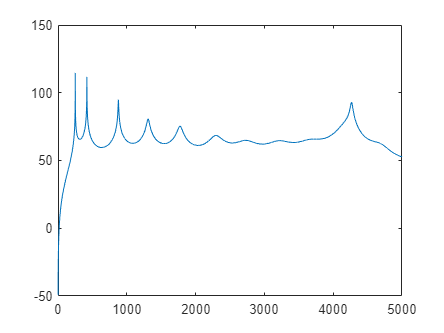

clear opts tbl

Data = [Freq SPL SPL_Phase];
%% need to change file name
save 'MA_Overall_3DOF_linear_driver_.txt' Data -ascii
plot(Freq,SPL);